# Nutrition based resource sharing

Num_individuals=100;
%Num_time_steps=120; %For inequitable nutrition based sharing
Num_time_steps=300; %For equitable nutrition based sharing
nut_init=50;
m_for=1;
m_nur=1;
mu=50;
nutrition_levels = nut_init*(0.9 + 0.2*rand(Num_individuals,1))

nutrition_levels =    50.0073
   52.8978
   45.6018
   52.3279
   46.9926
   47.6000
   46.8143
   50.8422
   47.9473
   45.2912



%In our simulation, nursing will be denoted by 1, and foraging by 2
worker_roles = ones(Num_individuals,Num_time_steps); %Initially workers all nurse until they are stimulated to go forage
food = 0; %Initialising no food available
food_share=zeros(1,Num_individuals)

food_share =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


R=4; %Amount of food collected by each forager
num_foragers=zeros(1,Num_time_steps); %Initialising number of foraagers

%p_vals = nutrition_levels./max(nutrition_levels) %For inequitable nutrition based sharing
p_vals = 1- nutrition_levels./max(nutrition_levels) %For equitable nutrition based sharing

p_vals =     0.0905
    0.0379
    0.1706
    0.0483
    0.1453
    0.1343
    0.1486
    0.0753
    0.1280
    0.1763


Sk = exp(p_vals)./(sum(exp(p_vals))) 

Sk =     0.0099
    0.0094
    0.0108
    0.0095
    0.0105
    0.0104
    0.0105
    0.0098
    0.0103
    0.0108


ans = 1

q =          0
    0.8400
    0.9000
    0.8100
    0.9300
    0.9200
    0.8900
    0.9100
    0.9500
    0.9100


p1 =     0.4500    0.6100    0.5100    0.3200    0.2500    0.2100    0.1600    0.1900    0.2000    0.2900    0.2600    0.2600    0.2300    0.2200    0.2500    0.2300    0.2600    0.2700    0.2600    0.2300    0.2400    0.2200    0.2200    0.2500    0.2700    0.2800    0.2300    0.2200    0.1800    0.2300    0.2800    0.3000    0.2500    0.2200    0.2100    0.2400    0.3300    0.2600    0.2000    0.2200    0.2400    0.2200    0.2500    0.2800    0.2100    0.1900    0.2400    0.3100    0.3400    0.2700


p2 =     0.5500    0.3900    0.4900    0.6800    0.7500    0.7900    0.8400    0.8100    0.8000    0.7100    0.7400    0.7400    0.7700    0.7800    0.7500    0.7700    0.7400    0.7300    0.7400    0.7700    0.7600    0.7800    0.7800    0.7500    0.7300    0.7200    0.7700    0.7800    0.8200    0.7700    0.7200    0.7000    0.7500    0.7800    0.7900    0.7600    0.6700    0.7400    0.8000    0.7800    0.7600    0.7800    0.7500    0.7200    0.7900    0.8100    0.7600    0.6900    0.6600    0.7300


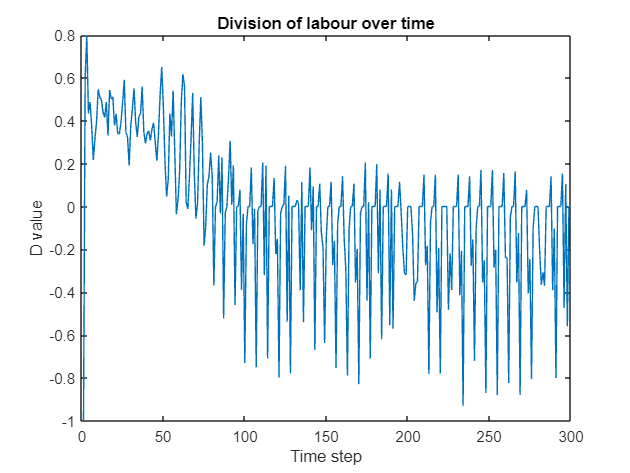


for time = 1:Num_time_steps
    for worker = 1:Num_individuals
        perception_err = -1+ 2*rand(); %Error with which they perceive their own hunger
        if nutrition_levels(worker) + perception_err<= mu
            worker_roles(worker,time) = 2;
        else
            worker_roles(worker,time)=1;
        end

        if worker_roles(worker,time)==1
            nutrition_levels(worker) =nutrition_levels(worker)-m_nur+ food_share(worker);
        else %if the role was 2
            nutrition_levels(worker) = nutrition_levels(worker)-m_for+ food_share(worker);
        end

    end
        nutrition_levels(1);
        %p_vals = nutrition_levels./max(nutrition_levels); %For inequitable nutrition based sharing
        p_vals = 1-nutrition_levels./max(nutrition_levels); %For equitable nutrition based sharing
        Sk = exp(p_vals)./(sum(exp(p_vals)));
        num_foragers(1,time) = sum(worker_roles(:,time)==2);
        food = R*num_foragers(1,time);
        food_share=food.*Sk;
end

## Number of nursers and foragers over time

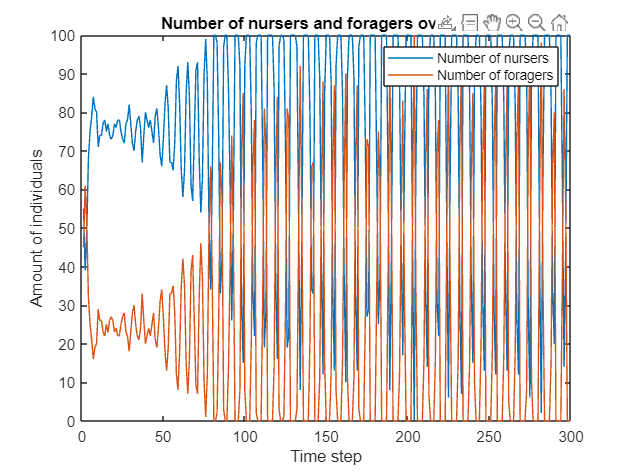

plot(100-num_foragers)
hold on
plot(num_foragers)
hold off
title('Number of nursers and foragers over time')
ylabel('Amount of individuals')
xlabel('Time step')

legend('Number of nursers', 'Number of foragers')

## Nutrition levels of the nursers and foragers

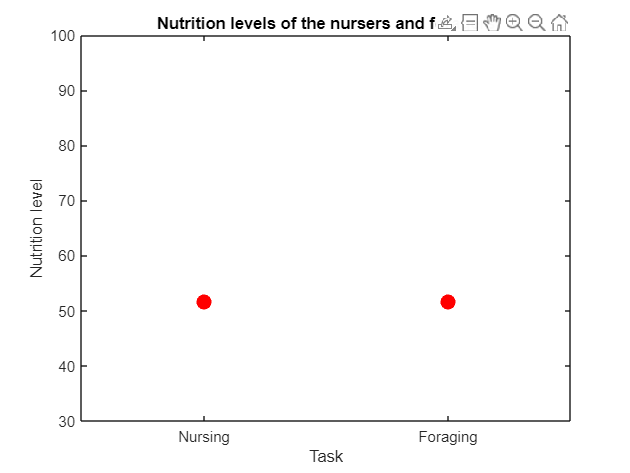

x = worker_roles(:,120);
x_categorical = categorical(x, [1 2], {'Nursing', 'Foraging'});

plot(x_categorical, nutrition_levels, 'r.', 'MarkerSize', 30)
xlabel('Task')
ylabel('Nutrition level')
ylim([30,100])
title('Nutrition levels of the nursers and foragers')

## Calculation of division of labour

repetitions = zeros(Num_time_steps,1);

for j = 2:Num_time_steps
    for i=1:100
           if worker_roles(i,j)==worker_roles(i,j-1)
                 repetitions(j)=repetitions(j)+1;
           end
    end
end

q = repetitions/Num_individuals
p1 = num_foragers./Num_individuals
p2 = (100-num_foragers)./Num_individuals

D = [];

for i =1:length(q)
    D(i) = q(i)./(p1(i).^2 + p2(i).^2) - 1;
end

## Division of labour over time plot

plot(1:Num_time_steps, D)
title('Division of labour over time')
ylabel('D value')
xlabel('Time step')

## Dominance values plot

worker_roles(:,120)

ans =      2
     2
     1
     2
     2
     2
     1
     2
     2
     2


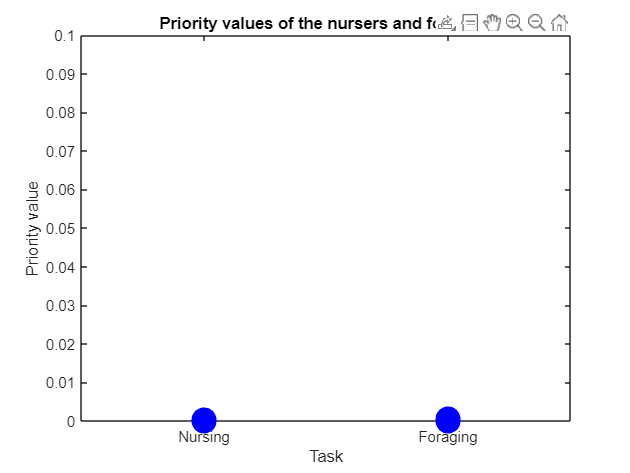

plot(x_categorical, p_vals, 'b.', 'MarkerSize', 50 )
xlabel('Task')
ylabel('Priority value')
ylim([0, 0.1])
title('Priority values of the nursers and foragers')